clear all;
ReadingPath = './output/Refocus/';
file = dir([ReadingPath, '*.png']);
name = string(extractfield(file, 'name')'); 
valueList = []


valueList =

     []



for i = 1:length(name)
    name1 = name(i);
    name1 = strsplit(name1, '_16bit');
    name1 = strsplit(name1(1), '_z'); name1 = name1(2);
    value = str2num(name1);
    valueList = [valueList, value];
end
[~,p] = sort(valueList);
name = name(p)

name = 200×1 string array
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-100_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-98.995_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-97.9899_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-96.9849_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-95.9799_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-94.9749_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-93.9698_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-92.9648_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-91.9598_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-90.9548_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-89.9497_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-88.9447_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-87.9397_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-86.9347_16bit.png"
    "Test_MultiParticle_refocus_stSS1_uvSS1_z-85.9296_16bit.png"
    

for i = 1:length(name)
    img{i} = imread(strcat(ReadingPath, name(i)));
end
img = cat(3,img{:});

BW = imbinarize(img,0.1);
L = bwlabeln(BW, 6);
M = max(L, [], 'all');
[s,k,n] = size(L);
maxI = zeros(M,n);
sumI = zeros(M,n);
for i = 1:10
    i
    [a,b,c] = ind2sub(size(L),find(L==i));
    NewL = ones(s,k,n);
    NewL(L(:) ~= i) = 0;
    NewL = uint16(NewL);
    NewImg = img .* NewL;
   
    for pp = 1:n
        %maxI(i,pp) = sum(NewImg(:,:,pp),[], 'all');
        sumI(i,pp) = sum(NewImg(:,:,pp),'all');
    end
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

z = sort(valueList)

z =  -100.0000  -98.9950  -97.9899  -96.9849  -95.9799  -94.9749  -93.9698  -92.9648  -91.9598  -90.9548  -89.9497  -88.9447  -87.9397  -86.9347  -85.9296  -84.9246  -83.9196  -82.9146  -81.9095  -80.9045  -79.8995  -78.8945  -77.8894  -76.8844  -75.8794  -74.8744  -73.8693  -72.8643  -71.8593  -70.8543  -69.8492  -68.8442  -67.8392  -66.8342  -65.8291  -64.8241  -63.8191  -62.8141  -61.8090  -60.8040  -59.7990  -58.7940  -57.7889  -56.7839  -55.7789  -54.7739  -53.7688  -52.7638  -51.7588  -50.7538


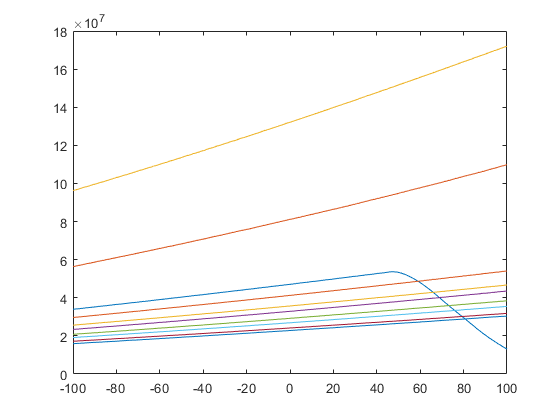

figure(1)
clf;
for i = 1:M
    plot(z, sumI(i,:));
    hold on;
end